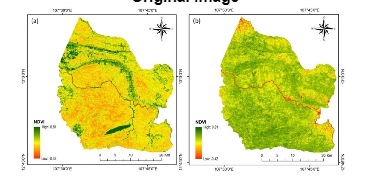

% Load satellite image
img = imread('C:/Users/LENOVO/Downloads/Land .jpg'); % Replace with your image
imshow(img);
title('Original Image');

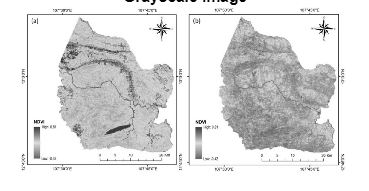

% Convert to grayscale
gray_img = rgb2gray(img);
figure;
imshow(gray_img);
title('Grayscale Image');

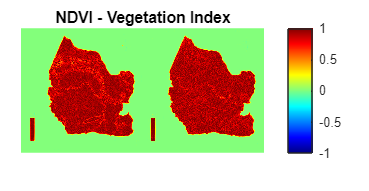

% Load the multispectral image
multispectral_image = imread('C:/Users/LENOVO/Downloads/Land .jpg'); % Replace with your file name

%Extract the NIR and Red bands(assuming NIR is the 4th band and Red is the 3rd band)
nir_band = multispectral_image(:, :, 2); % Adjust index based on your image
red_band = multispectral_image(:, :, 3); % Adjust index based on your image

% Convert to double for calculations
nir_band = double(nir_band);
red_band = double(red_band);

% Calculate NDVI
ndvi = (nir_band - red_band) ./ (nir_band + red_band);

% Display NDVI
figure;
imshow(ndvi, []);
title('NDVI - Vegetation Index');
colormap jet; % Optional: Apply a colormap for better visualization
colorbar; % Optional: Add a colorbar

gray_img = rgb2gray(img);
figure;
imshow(gray_img);
title('Grayscale Image');

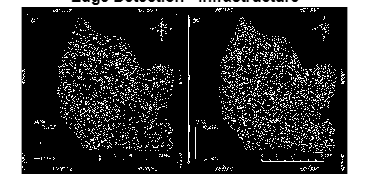

% Edge detection to identify urban areas
edges = edge(gray_img, 'Canny');
figure;
imshow(edges);
title('Edge Detection - Infrastructure');

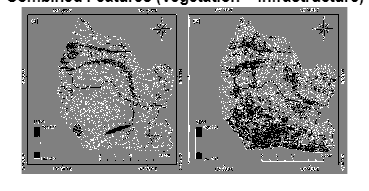

% Combine vegetation and edge data
combined_features = double(edges) + double(gray_img > 150); % Example threshold for brightness
figure;
imshow(combined_features, []);
title('Combined Features (Vegetation + Infrastructure)');

% Example: Generate a synthetic 'combined_features' matrix
% Replace this with your actual data loading or computation
combined_features = rand(100, 100); % Random data for demonstration

% Threshold for poverty levels
threshold_value = 0.5; % Define threshold
poverty_map = combined_features > threshold_value; % Apply thresholding

% Display the Poverty Detection Map
figure;
imshow(poverty_map, []);
title('Poverty Detection Map');

 % Apply a colormap for visualization
colormap_image = ind2rgb(poverty_map, jet(256)); % Create RGB image with colormap

% Save the colored image
imwrite(colormap_image, 'colored_poverty_map.png');

% Display confirmation
disp('Colored Poverty Map Saved!');

Colored Poverty Map Saved!


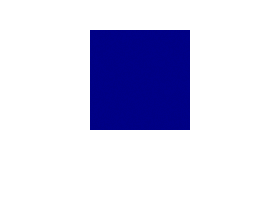

imshow(colormap_image);